%{
ES115 Engineering Computer Applications 
Module 1 Project: Bridge Deflection Model Comparison

Author: Luis A. Lamas Carreto
Instructor: Lynroy Grant
Date: April 20, 2026

Purpose:
The purpose of this project is to analyze bridge beam deflection using 
quadratic modeling. It compares a baseline physical model against two 
alternatives to perform sensitivity analysis on material stiffness a 
and initial settlement c.

Inputs:
- Usage Range (x): 0 to 10 meters.
- Step Size: 0.25 meters.
- Model 1 (Baseline): a=0.5, b=-5, c=0.
- Model 2 (Alt a): a=0.8 (representing a stiffer beam).
- Model 3 (Alt c): c=-2 (representing initial settlement).

Outputs:
- Deflection Vectors (d1, d2, d3): mm of deflection across the beam.
- Minima Reports: The location and magnitude of max deflection for each model.
- Visualization: A comparison plot identifying critical stress points.

Engineering Workflows:
- Quadratic Modeling: Implementing d(x) = ax^2 + bx + c.
- Sensitivity Analysis: Changing single variables to observe system impact.
- Optimization: Using the min() function to find critical failure points.

MATLAB Tools:
- min(): Identifies maximum deflection values and their indices.
- plot(): Visualizes the structural curves.
- fprintf(): Generates the summary report in the command window.
%}

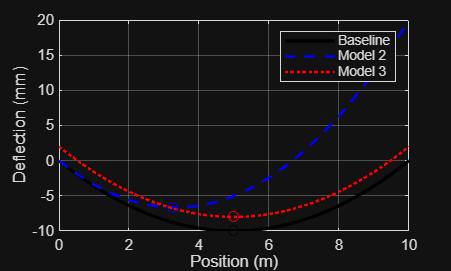

x = 0:0.25:10;

a1 = 0.4;  b1 = -4;  c1 = 0; 
a2 = 0.6;  
c3 = 2;    

d1 = a1*x.^2 + b1*x + c1;       
d2 = a2*x.^2 + b1*x + c1;       
d3 = a1*x.^2 + b1*x + c3;       

[val1, idx1] = min(d1);
[val2, idx2] = min(d2);
[val3, idx3] = min(d3);

figure;
plot(x, d1, 'k-', 'LineWidth', 2); hold on;
plot(x, d2, 'b--', 'LineWidth', 1.5);
plot(x, d3, 'r:', 'LineWidth', 1.5);
plot(x(idx1), val1, 'ko', x(idx2), val2, 'bo', x(idx3), val3, 'ro');
grid on;
xlabel('Position (m)');
ylabel('Deflection (mm)');
legend('Baseline', 'Model 2', 'Model 3');


fprintf('Model 1 Min: %.2f mm at %.2f m\n', val1, x(idx1));

Model 1 Min: -10.00 mm at 5.00 m


fprintf('Model 2 Min: %.2f mm at %.2f m\n', val2, x(idx2));

Model 2 Min: -6.66 mm at 3.25 m


fprintf('Model 3 Min: %.2f mm at %.2f m\n', val3, x(idx3));

Model 3 Min: -8.00 mm at 5.00 m
